%MAE 180 PROJ S-3 TEAM CODE

clc
clear
format long

%% Common parameters for both runs
lat = 32.8811913;    % Site latitude (phi) in degrees
alt = 111E-3;        % Site altitude in km
JD_prop = 2460542.7792; % Propagation Julian Date (second value given on file)

%% First Run: Group S-3 (ADVENTURE 1)
% Days (JD), right ascension (ra), declination (dec), and local sidereal time (lst)
JD_s1  = [2460262.842373029;
       2460262.842893863;
       2460262.843414696];
   
ra_s1  = [135.514066681081;
       148.057402685433;
       165.762330451468];

dec_s1 = [29.155447177193;
       45.578290874916;
       56.881276513171];

lst_s1 = [59.199692009582;
       59.387705356210;
       59.575718703254];

%% Second Run: Group K-3 (THE MARTIANS)
% Fill in the missing values with the Group K-3 data
JD_s2  = [2460267.322080967;
       2460267.322601800;
       2460267.323122634];
   
ra_s2  = [192.359369943852;
       206.417534213015;
       226.142267971101];

dec_s2 = [-25.796600080803;
       -26.271136667762;
       -25.487019970794];

lst_s2 = [236.309961929603;
       236.497975276648;
       236.685988623275];
%CONSTANTS
mu= 398600.4354; %km^3/s^2
Rearth= 6378.1366; %km
smallomegaearth= 7.2921159E-5; %rad/s
Areatomassratio= 0.0123; %m^2/kg
JDday2secondconversionunit = 86400; 
J2 = 0.0010826267; %unitless
CD = 1.28; % drag coefficient corrected from annocement 
we = 7.2921159E-5;% Earth's inertial rotation rate

% UCSD coords
lot=deg2rad(-117.2336137);

% convert JD to seconds and units to radians
JD_s1 = JD_s1 * JDday2secondconversionunit;
JD_prop = JD_prop * JDday2secondconversionunit;
lat = deg2rad(lat);
lst_s1 = deg2rad(lst_s1);
ra_s1 = deg2rad(ra_s1);
dec_s1 = deg2rad(dec_s1);

JD_s2 = JD_s2 * JDday2secondconversionunit;
lst_s2 = deg2rad(lst_s2);
ra_s2 = deg2rad(ra_s2);
dec_s2 = deg2rad(dec_s2);

[r0_s1,v0_s1] = gauss(lat, lst_s1, alt, ra_s1, dec_s1, JD_s1, JD_prop);
[r0_s2,v0_s2] = gauss(lat, lst_s2, alt, ra_s2, dec_s2, JD_s2, JD_prop);


% 10. Compute initial orbital elements from r0 and v0
oe0_s1 = ComputeOrbitalElements(r0_s1, v0_s1, mu);
oe0_s2 = ComputeOrbitalElements(r0_s2, v0_s2, mu);


% Initial state vector
y0_s1 = [r0_s1';v0_s1';];
y0_s2 = [r0_s2';v0_s2';];

% Satelite 1 starts before satelite 2
% Propegate satelite 1 until the start of satelite 2
% Then propogate them together to find closest distance
A2M_convert = Areatomassratio / 1000000;  % m^2/kg to km^2/kg

JD_init_s1 = JD_s1(2);
JD_init_s2 = JD_s2(2);
t_prop_s1tos2 = JD_init_s2 - JD_init_s1;
tspan_s1tos2 = [0, t_prop_s1tos2];
options = odeset('RelTol',1e-7,'AbsTol',1e-7);
[t_s1tos2, Y_s1tos2] = ode45(@(t, y) one_sat_sim(t, y, mu, J2, Rearth, A2M_convert,CD), tspan_s1tos2, y0_s1, options);

% New positions of our first satelite when the second satelite starts
r0_s1_new = Y_s1tos2(end,1:3);
v0_s1_new = Y_s1tos2(end,4:6);

% Now propogate the satelites at the same time from the same start time
% Compare the distance between each at every step and find the minimum

JD_init = JD_s2(2);
JD_end = JD_prop;
t_prop = JD_end - JD_init;
tspan = [0, t_prop];
options = odeset('RelTol',1e-7,'AbsTol',1e-7);

y0_big = [r0_s1_new'; v0_s1_new'; y0_s2;]

y0_big = 1.0e+03 *

   0.877543702906890
  -0.273578926608038
   6.811948532909926
  -0.001618220848354
  -0.007435697957746
  -0.000082885832559
  -3.769838525508065
  -4.870572806985832
   3.014506061429519
   0.006352967972696



[t, Y] = ode45(@(t, y) two_sat_sim(t, y, mu, J2, Rearth, A2M_convert,CD), tspan, y0_big, options);

min_distance =      7.559833572071628e+03


min_distance =      7.557942585469777e+03


min_distance =      7.556996559597753e+03


min_distance =      7.552266211685741e+03


min_distance =      7.551425002345447e+03


min_distance =      7.550373376570880e+03


min_distance =      7.550373373128042e+03


min_distance =      7.540909584657858e+03


min_distance =      7.536164400802143e+03


min_distance =      7.512433403095741e+03


min_distance =      7.508208387863288e+03


min_distance =      7.502923958226366e+03


min_distance =      7.502923526276946e+03


min_distance =      7.455386017348582e+03


min_distance =      7.431288139511196e+03


min_distance =      7.310721069803655e+03


min_distance =      7.289170178784516e+03


min_distance =      7.262113671826743e+03


min_distance =      7.262058726417620e+03


min_distance =      7.141636336785878e+03


min_distance =      7.079501831003929e+03


min_distance =      6.769129048145367e+03


min_distance =      6.713739754325805e+03


min_distance =      6.643347334354011e+03


min_distance =      6.642481060045296e+03


min_distance =      6.496907395552846e+03


min_distance =      6.421895367359306e+03


min_distance =      6.048619840131675e+03


min_distance =      5.982476431969456e+03


min_distance =      5.898209561587796e+03


min_distance =      5.896840067143220e+03


min_distance =      5.730844929569190e+03


min_distance =      5.645688809602778e+03


min_distance =      5.224764777460987e+03


min_distance =      5.150981463807641e+03


min_distance =      5.056954691191097e+03


min_distance =      5.055113908388423e+03


min_distance =      4.879691628454701e+03


min_distance =      4.790437615430810e+03


min_distance =      4.354745029762016e+03


min_distance =      4.279685647442081e+03


min_distance =      4.184451020308206e+03


min_distance =      4.182419150181373e+03


min_distance =      4.026244097596338e+03


min_distance =      3.947895936063766e+03


min_distance =      3.573628804690115e+03


min_distance =      3.510795878188417e+03


min_distance =      3.432205450635745e+03


min_distance =      3.430770990313915e+03


min_distance =      3.310328076719515e+03


min_distance =      3.251135736223155e+03


min_distance =      2.979864056332822e+03


min_distance =      2.936522399334329e+03


min_distance =      2.883691165166867e+03


min_distance =      2.882952412548421e+03


min_distance =      2.805593919658742e+03


min_distance =      2.768924185718170e+03


min_distance =      2.615519331475895e+03


min_distance =      2.593782182237609e+03


min_distance =      2.568765723378300e+03


min_distance =      2.568511564565101e+03


min_distance =      2.527698578331732e+03


min_distance =      2.511096282748908e+03


min_distance =      2.475461538243174e+03


min_distance =      2.455836046357421e+03


min_distance =      2.453304279771605e+03


min_distance =      2.452388128089299e+03


min_distance =      2.439227532486409e+03


min_distance =      2.427144498629736e+03


min_distance =      2.414130780447710e+03


min_distance =      2.413946543940868e+03


min_distance =      2.398610657432350e+03


min_distance =      2.393211264645162e+03


min_distance =      2.356821102682964e+03


min_distance =      2.335756639516012e+03


min_distance =      2.265715367422534e+03


min_distance =      2.259373127365199e+03


min_distance =      2.253948241988901e+03


min_distance =      2.253877904041998e+03


min_distance =      2.251765810063076e+03


min_distance =      2.229023497622657e+03


min_distance =      2.217821341508525e+03


min_distance =      2.206079183350962e+03


min_distance =      2.205921205385077e+03


min_distance =      2.192819782444381e+03


min_distance =      2.188894004602293e+03


min_distance =      2.141880792538163e+03


min_distance =      2.125295975529063e+03


min_distance =      2.106492109387027e+03


min_distance =      2.106231391781771e+03


min_distance =      2.078348324272195e+03


min_distance =      2.067400800986231e+03


min_distance =      2.050889142634171e+03


min_distance =      2.039505833752627e+03


min_distance =      2.023802635876100e+03


min_distance =      1.985166790868415e+03


min_distance =      1.985099097955008e+03


min_distance =      1.961739309593421e+03


min_distance =      1.961438889952469e+03


min_distance =      1.917822004471116e+03


min_distance =      1.899231082990568e+03


min_distance =      1.848112438502289e+03


min_distance =      1.846304883010048e+03


min_distance =      1.844547102459234e+03


min_distance =      1.827004151380146e+03


min_distance =      1.782082876048278e+03


min_distance =      1.781517576511805e+03


min_distance =      1.740854231510511e+03


min_distance =      1.718848225877575e+03


min_distance =      1.650086974090788e+03


min_distance =      1.645264390410015e+03


min_distance =      1.642370988827938e+03


min_distance =      1.642349320759220e+03


min_distance =      1.618719641383502e+03


min_distance =      1.604016449876635e+03


min_distance =      1.578358499871480e+03


min_distance =      1.547521067567407e+03


min_distance =      1.528676180189522e+03


min_distance =      1.507167928511995e+03


min_distance =      1.506929811217228e+03


min_distance =      1.471029525618091e+03


min_distance =      1.457480214118686e+03


min_distance =      1.441680219000827e+03


min_distance =      1.386533257021927e+03


min_distance =      1.379426334504203e+03


min_distance =      1.373812601879644e+03


min_distance =      1.373765241305528e+03


min_distance =      1.301112155209900e+03


min_distance =      1.285131593975908e+03


min_distance =      1.267763678477273e+03


min_distance =      1.267579054354371e+03


min_distance =      1.242221875077000e+03


min_distance =      1.235022376539803e+03


min_distance =      1.219876945322562e+03


min_distance =      1.219684389654017e+03


min_distance =      1.187127595283611e+03


min_distance =      1.176155668619543e+03


min_distance =      1.127452276383760e+03


min_distance =      1.107496442659364e+03


min_distance =      1.085096572373690e+03


min_distance =      1.084874871570428e+03


min_distance =      1.049133049103734e+03


min_distance =      1.037021623392594e+03


min_distance =      1.021632738702391e+03


min_distance =      1.001679641569101e+03


min_distance =      1.001491793500770e+03


min_distance =      9.719861826647452e+02


min_distance =      9.635879912985769e+02


min_distance =      9.499450841364820e+02


min_distance =      9.216074620468330e+02


min_distance =      8.292607576438249e+02


min_distance =      8.227200014222578e+02


min_distance =      8.190164831457190e+02


min_distance =      8.189990605681626e+02


min_distance =      8.126349006771642e+02


min_distance =      8.122923780686380e+02


min_distance =      7.737594835337933e+02


min_distance =      7.614982315816065e+02


min_distance =      7.397317303495118e+02


min_distance =      7.390887145397985e+02


min_distance =      6.803514796793490e+02


min_distance =      6.567362292200824e+02


min_distance =      6.140594140779335e+02


min_distance =      5.512449516004027e+02


min_distance =      5.459744645898697e+02


min_distance =      4.191442951224363e+02


min_distance =      4.080822637888809e+02


min_distance =      4.045172725071208e+02


min_distance =      3.695619711139051e+02


min_distance =      3.501390438846896e+02


min_distance =      3.379357156609354e+02


min_distance =      3.378715686830197e+02


min_distance =      2.702162357235782e+02


min_distance =      2.336801426773578e+02


min_distance =      2.035386228053040e+02


min_distance =      2.032600393277603e+02


min_distance =      1.694504669035524e+02


min_distance =      1.686692730349182e+02


min_distance =      1.550714086635876e+02


min_distance =      1.330355505831396e+02


min_distance =   74.645734609516694


min_distance =   50.894384944176061


min_distance =   24.047097967391448



r_end_s1 = Y(end,1:3);
v_end_s1 = Y(end,4:6);
r_end_s2 = Y(end,7:9);
v_end_s2 = Y(end,10:12);



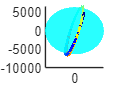




% Downsample the orbit for better performance
step = 500; % Adjust to balance performance & smoothness
Y_downsampled = Y(1:step:end, :);
numPoints = size(Y_downsampled, 1);

% Generate a color gradient
cmap = jet(numPoints);

figure;
hold on;

% Plot the rainbow-colored orbit without legend spam
for i = 1:numPoints-1
    plot3(Y_downsampled(i:i+1,1), Y_downsampled(i:i+1,2), Y_downsampled(i:i+1,3), ...
        'Color', cmap(i,:), 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Prevent legend spam
end



% Plot Earth
[X, Y2, Z] = sphere(50);
X = X * Rearth;
Y2 = Y2 * Rearth;
Z = Z * Rearth;
surf(X, Y2, Z, 'FaceColor', 'c', 'EdgeColor', 'none'); 
alpha(0.6);


% Plot r0 and r_end with distinct markers (only these go in legend)
scatter3(r0(1), r0(2), r0(3), 150, 'r', 'filled', 'o', 'DisplayName', 'Initial Position');

Unrecognized function or variable 'r0'.

scatter3(r_end(1), r_end(2), r_end(3), 150, 'g', 'filled', 'o', 'DisplayName', 'Final Position');

% Labels and Formatting
xlabel('X (km)');
ylabel('Y (km)');
zlabel('Z (km)');
title('Rainbow Satellite Orbit with J2 Perturbation and Atmospheric Drag');
grid on;
axis equal;
legend('Location', 'best'); % Only shows r0 and r_end
view(3);
hold off;

r = r_end;
v = v_end;